clc; clear; 
load('C:\Users\Arshia\Desktop\StableLearningInBiologicalSNN\Analysis\Part1(StabilizationOfSingleMemory)\Data\Scaled50\N400\Apr_28_2025_18_30_02\MemoryRepresentations.mat');
load('C:\Users\Arshia\Desktop\StableLearningInBiologicalSNN\Analysis\Part1(StabilizationOfSingleMemory)\Data\Scaled50\N400\Apr_28_2025_18_30_02\Patch1.mat');
whos

  Name                    Size                 Bytes  Class                Attributes

  data1                   1x1              274640030  struct                         
  delays               1000x400              3200000  double                         
  obj                     1x1                      8  IzhikevichNetwork              
  orders_separate      1000x400              3200000  double                         
  orders_together      1000x400              3200000  double                         
  spike_counts         1000x400              3200000  double                         




net = obj;

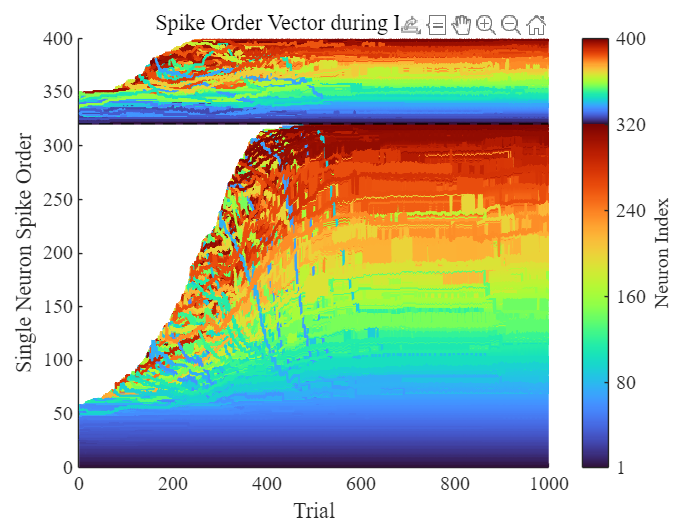


check_flag_save = orders_separate;

%% Order of spikes analysis (In input mode!)
figure('Name', "Single Neuron Spike Order")
fsize = 15;
temp = check_flag_save(1:1:end, :);
temp(temp == 0) = nan;

%active_ex_cells = find(temp(end, :) ~= 0 & temp(end, :) <= net.Ne);
%active_inh_cells = find(temp(end, :) ~= 0 & temp(end, :) > net.Ne);

stable_order_ex = check_flag_save(end, 1:320);
stable_order_inh = check_flag_save(end, 321:end)-320;
stable_order_ex(stable_order_ex == 0) = net.Ne-sum(stable_order_ex == 0)+1:net.Ne;
stable_order_inh(stable_order_inh == -320) = net.Ni-sum(stable_order_inh == -320)+1:net.Ni;

colormap_ex_init = turbo(320);
colormap_ex = colormap_ex_init(stable_order_ex, :);

colormap_inh_init = turbo(80);
colormap_inh = colormap_inh_init(stable_order_inh, :);

hold on 
wsize = 1.5;
for cell_id =1:320
    
    plot(temp(1:end, cell_id), 'color', colormap_ex(cell_id, :), LineWidth= wsize)
end
for cell_id = 321:400
    
    plot(temp(1:end, cell_id), 'color', colormap_inh(cell_id-320, :), LineWidth= wsize)
end

plot([0 1000], 320.5*[1 1], 'k--', HandleVisibility='off');

% Combine colormaps and apply to figure
full_colormap = [colormap_ex_init; colormap_inh_init];  % 400 x 3
colormap(full_colormap);                      % set figure colormap

% Set color axis and add colorbar
caxis([1, 400]);                              % map neuron index to color range
cb = colorbar;
cb.Ticks = [1, 80, 160, 240, 320, 400];       % adjust ticks as needed
cb.TickLabels = {'1','80','160','240','320','400'};
cb.Label.String = 'Neuron Index';
cb.FontName = 'Times New Roman';
cb.FontSize = 12;


xlabel("Trial")
ylabel("Single Neuron Spike Order")
title("Spike Order Vector during Learning", 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'normal')
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'normal');
print(gcf, "SpikeOrderSeparate.png", '-dpng', '-r300')
exportgraphics(gcf, "SpikeOrderSeparate.pdf", ContentType="auto")

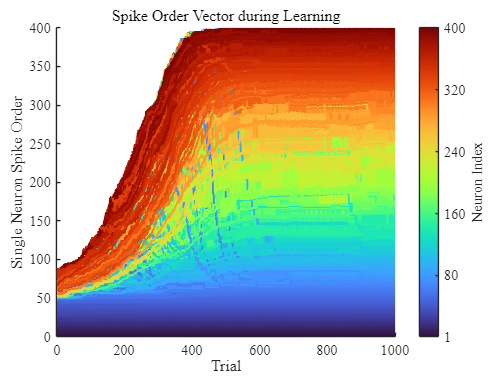

check_flag_save = orders_together;

%% Order of spikes analysis (In input mode!)
figure('Name', "Single Neuron Spike Order")
fsize = 15;
temp = check_flag_save(1:1:end, :);
temp(temp == 0) = nan;

%active_ex_cells = find(temp(end, :) ~= 0 & temp(end, :) <= net.Ne);
%active_inh_cells = find(temp(end, :) ~= 0 & temp(end, :) > net.Ne);

stable_order_ex = check_flag_save(end, :);
% stable_order_inh = check_flag_save(end, 321:end)-320;
% stable_order_ex(stable_order_ex == 0) = net.Ne-sum(stable_order_ex == 0)+1:net.Ne;
% stable_order_inh(stable_order_inh == -320) = net.Ni-sum(stable_order_inh == -320)+1:net.Ni;

colormap_ex_init = turbo(400);
colormap_ex = colormap_ex_init(stable_order_ex, :);

hold on 
wsize = 1.5;
for cell_id =1:400
    plot(temp(1:end, cell_id), 'color', colormap_ex(cell_id, :), LineWidth= wsize)
end

% Combine colormaps and apply to figure
full_colormap = [colormap_ex_init];  % 400 x 3
colormap(full_colormap);                      % set figure colormap

% Set color axis and add colorbar
caxis([1, 400]);                              % map neuron index to color range
cb = colorbar;
cb.Ticks = [1, 80, 160, 240, 320, 400];       % adjust ticks as needed
cb.TickLabels = {'1','80','160','240','320','400'};
cb.Label.String = 'Neuron Index';
cb.FontName = 'Times New Roman';
cb.FontSize = 12;


xlabel("Trial")
ylabel("Single Neuron Spike Order")
title("Spike Order Vector during Learning", 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'normal')
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'normal');
print(gcf, fullfile("Results", "SpikeOrderTogether.png"), '-dpng', '-r300')
exportgraphics(gcf, fullfile("Results", "SpikeOrderTogether.pdf"), ContentType="auto")